mu = 0.01215; % Earth-Moon

poly1 = [1  -1*(3-mu)  (3-2*mu)  -mu   2*mu  -mu ];

rt1 = roots(poly1)

rt1 =    1.4946 + 0.8613i
   1.4946 - 0.8613i
  -0.0762 + 0.1458i
  -0.0762 - 0.1458i
   0.1509 + 0.0000i


for k=1:5
    if isreal(rt1(k)) 
        gamma = rt1(k)
    end
end

gamma = 0.1509


xL = (1-mu)-gamma

xL = 0.8369

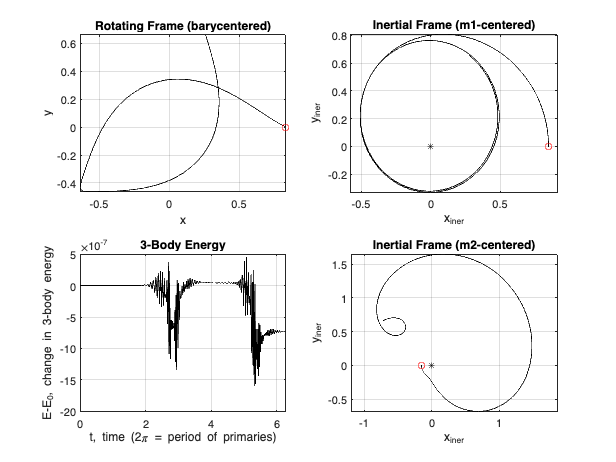


T = 2*pi ; % period of primaries in non-dimensional units

tfinal = 1*T;

tspan = 0:0.001*T:tfinal;

x0 = xL - 0.001 ; % displaced from equil. a little to the 'left'

X0 = [ x0 0 0 0 ]; % initial condition

opts = odeset('AbsTol',1e-8,'RelTol',1e-6);
[t,X] = ode45(@(t,X) prtbp(t,X,mu), tspan, X0, opts) ;

x =X(:,1); 
y =X(:,2);
vx=X(:,3);
vy=X(:,4);

Xin = rot2iner(X,t,1,mu);

subplot(2,2,1)
plot(x,y,'k',X0(1),X0(2),'ro');
title('Rotating Frame (barycentered)'); 
xlabel('x'); ylabel('y');
axis equal; grid on

subplot(2,2,2)
plot(Xin(:,1),Xin(:,2),'k',Xin(1,1),Xin(1,2),'ro',0,0,'k*');
title('Inertial Frame (m1-centered)'); 
xlabel('x_{iner}'); ylabel('y_{iner}');
axis equal; grid on

Xin = rot2iner(X,t,2,mu);

subplot(2,2,4)
plot(Xin(:,1),Xin(:,2),'k',Xin(1,1),Xin(1,2),'ro',0,0,'k*');
title('Inertial Frame (m2-centered)'); 
xlabel('x_{iner}'); ylabel('y_{iner}');
axis equal; grid on

E = energy(X,mu);
subplot(2,2,3)
plot(t,E-E(1),'k')
title('3-Body Energy')
xlabel('t, time (2\pi = period of primaries)')
ylabel('E-E_0, change in 3-body energy')
grid on

std(E)

ans = 3.4374e-07

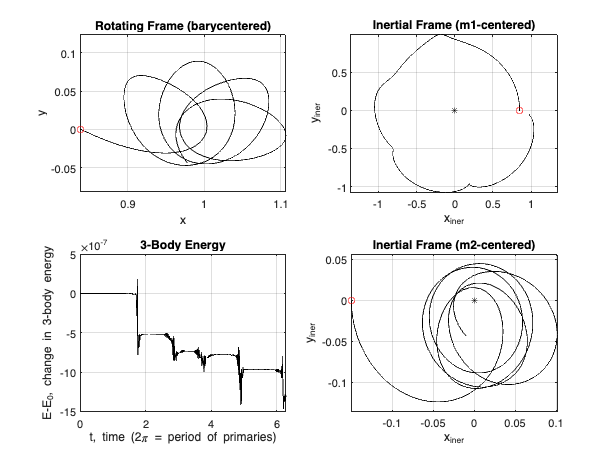

x0 = xL + 0.001 ; % displaced from equil. a little to the 'right'

X0 = [ x0 0 0 0 ]; % initial condition

tfinal = 1*T;

tspan = 0:0.001*T:tfinal;

opts = odeset('AbsTol',1e-8,'RelTol',1e-6);
[t,X] = ode45(@(t,X) prtbp(t,X,mu), tspan, X0, opts) ;

x =X(:,1); 
y =X(:,2);
vx=X(:,3);
vy=X(:,4);

subplot(2,2,1)
plot(x,y,'k',X0(1),X0(2),'ro');
title('Rotating Frame (barycentered)'); 
xlabel('x'); ylabel('y');
axis equal; grid on

Xin = rot2iner(X,t,1,mu);

subplot(2,2,2)
plot(Xin(:,1),Xin(:,2),'k',Xin(1,1),Xin(1,2),'ro',0,0,'k*');
title('Inertial Frame (m1-centered)'); 
xlabel('x_{iner}'); ylabel('y_{iner}');
axis equal; grid on

Xin = rot2iner(X,t,2,mu);

subplot(2,2,4)
plot(Xin(:,1),Xin(:,2),'k',Xin(1,1),Xin(1,2),'ro',0,0,'k*');
title('Inertial Frame (m2-centered)'); 
xlabel('x_{iner}'); ylabel('y_{iner}');
axis equal; grid on

E = energy(X,mu);
subplot(2,2,3)
plot(t,E-E(1),'k')
title('3-Body Energy')
xlabel('t, time (2\pi = period of primaries)')
ylabel('E-E_0, change in 3-body energy')
grid on

std(E)

ans = 3.8902e-07


% L1 eigenbasis

mubar=mu/abs(xL-1+mu)^3 + (1-mu)/abs(xL+mu)^3;

a=1+2*mubar;
b=mubar -1 ;

lam = sqrt( 0.5*(mubar-2+sqrt(9*mubar^2-8*mubar)));
nu  = sqrt(-0.5*(mubar-2-sqrt(9*mubar^2-8*mubar)));

sigma =  2*lam/(lam^2 + b)

sigma = 0.4601

tau   =-(nu^2  + a)/(2*nu)

tau = -3.5865


u1 = [ 1 ; -sigma ;  lam ; -lam*sigma ] ;
u2 = [ 1 ;  sigma ; -lam ; -lam*sigma ] ;
u  = [ 1 ;    0   ;   0  ;   nu*tau   ] ;
v  = [ 0 ;   tau  ;  -nu ;     0      ] ;


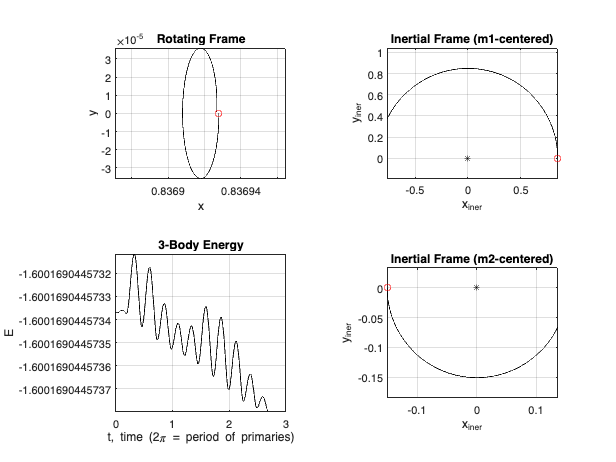

% Compute small periodic orbit (planar Lyapunov orbit)

tfinal = 2*pi/nu;

tspan = 0:0.001*T:tfinal;

XL = [ xL ; 0 ; 0 ; 0 ] ;

displacement = 1e-5; % nondimensional displacement from L
X0 = XL + displacement*u ; % initial condition

opts = odeset('AbsTol',1e-8,'RelTol',1e-6);
[t,X] = ode45(@(t,X) prtbp(t,X,mu), tspan, X0, opts) ;

x =X(:,1); 
y =X(:,2);
vx=X(:,3);
vy=X(:,4);

subplot(2,2,1)
plot(x,y,'k',X0(1),X0(2),'ro');
title('Rotating Frame'); 
xlabel('x'); ylabel('y');
axis equal; grid on

Xin = rot2iner(X,t,1,mu);

subplot(2,2,2)
plot(Xin(:,1),Xin(:,2),'k',Xin(1,1),Xin(1,2),'ro',0,0,'k*');
title('Inertial Frame (m1-centered)'); 
xlabel('x_{iner}'); ylabel('y_{iner}');
axis equal; grid on

Xin = rot2iner(X,t,2,mu);

subplot(2,2,4)
plot(Xin(:,1),Xin(:,2),'k',Xin(1,1),Xin(1,2),'ro',0,0,'k*');
title('Inertial Frame (m2-centered)'); 
xlabel('x_{iner}'); ylabel('y_{iner}');
axis equal; grid on

E = energy(X,mu);
subplot(2,2,3)
plot(t,E-E(1),'k')
title('3-Body Energy')
xlabel('t, time (2\pi = period of primaries)')
ylabel('E-E_0, change in 3-body energy')
grid on

std(E)

ans = 1.6416e-13

function xdot = prtbp(t,x,mu)
% xdot = prtbp(t,x,mu)
%
% with the LARGER MASS, m1 to the left of the origin at (-mu,0)
% and m2, or the planet (ie. Earth), is at (1 - mu, 0)
%
%                L4
%
% -L3----m1--+-------L1--m2--L2-
%
%                L5
%
% Shane Ross (revised 9.23.97)

mu1=1-mu; % mass of larger  primary (nearest origin on left)
mu2=  mu; % mass of smaller primary (furthest from origin on right)

r3= ((x(1)+mu2)^2 + x(2)^2)^1.5;     % r: distance to m1, LARGER MASS
R3= ((x(1)-mu1)^2 + x(2)^2)^1.5;     % R: distance to m2, smaller mass

xdot    = zeros(4,1);
xdot(1) = x(3);
xdot(2) = x(4);
xdot(3) = x(1)-(mu1*(x(1)+mu2)/r3) -(mu2*(x(1)-mu1)/R3)+2*x(4);
xdot(4) = x(2)-(mu1* x(2)     /r3) -(mu2* x(2)     /R3)-2*x(3);
end


%%
function E = energy(X,mu)

mu1=1-mu;mu2=mu;

Vsqrd= X(:,3).^2+X(:,4).^2 ;
Ubar = - mu1./sqrt((X(:,1)+mu2).^2+X(:,2).^2) ...
       - mu2./sqrt((X(:,1)-mu1).^2+X(:,2).^2) ...
       - 0.5*(X(:,1).^2+X(:,2).^2) - 0.5*mu1*mu2 ;

E = 0.5*Vsqrd + Ubar ;

end


function Xin = rot2iner(X,t,M,mu,del)
% Xin=rot2iner(X,T,M,mu,del);
%
% Transformation from M body-centered rotating (nondim.) coordinates to
% inertial (nondim.) coordinates
%
% M = 2 : smaller mass(M2) centered inertial coordinates
% M = 1 : LARGER  mass(M1) centered inertial coordinates
% M = 0 : center-of-mass   centered inertial coordinates
%
% X   = state 4- or 6-vector matrix (in nondim. rotating coordinates)
% t   = nondimensional CR3BP time
% del = the rotation offset at time t=0 (in radians)
%
% Xrot = inv(B)*(Xin - A)
% see p.6 of Cassall(1996)
%
% NOTE: nondim. means nondimensional CR3BP units where 
%	sum of primaries' mass = 1
%	constant distance between primaries = 1
%	period of primaries' orbit = 2*pi
% 
%-----------------------------------------------------------------------
% CR3BP (Circular Restricted Three-Body [Gravitational] Problem)
% with the LARGER MASS, M1 to the left of the origin at (-mu,0)
% and the smaller mass, M2, or the planet (ie. Earth), is at (1 - mu, 0)
%
%       (rotating coords)
%
%                 L4
% -L3------M1--+-----L1--M2--L2-
%                 L5
%
% Shane Ross (revised 7.15.97)
%

% Defaults
if nargin<=4
    del=0;
    if nargin<=3
        mu=0;
        if nargin<=2
            M=0;
        end
    end
end

if     M==1, d= -mu; 	% distance to LARGER  primary in CR3BP (M1)
elseif M==2, d=1-mu;	% distance to smaller primary in CR3BP (M2)
elseif M==0, d=0;	    % center-of-mass is the origin
end

c=cos(t + del); s=sin(t + del);

Xin=[];
Xin(:,1)= c.*(X(:,1)-d) - s.*X(:,2);
Xin(:,2)= s.*(X(:,1)-d) + c.*X(:,2);
Xin(:,3)=-s.*(X(:,1)+X(:,4)-d) + c.*(X(:,3) - X(:,2));
Xin(:,4)= c.*(X(:,1)+X(:,4)-d) + s.*(X(:,3) - X(:,2));

end

